***Wireless Communications EL-GY 6023***

Homework 8 - Tommy Azzino (ta1731)

Problem 3

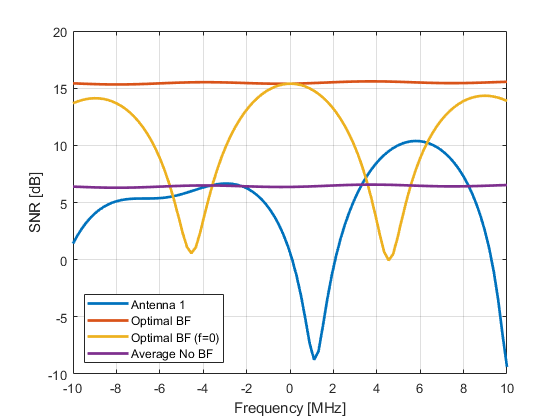

npoints = 100;
freqs = linspace(-10,10,npoints)*1e6;
path_phase = deg2rad([0, 180, 65]);
aoa = deg2rad([30, -30, 80]);
delay = [0, 100, 130]*1e-9;
N = 8;
n = (0:N-1)';
u = exp(n*sin(aoa)*1i*pi);
snr = [4, 1, -2];
snr_a = zeros(npoints,1);
snr_b = zeros(npoints,1);
snr_c = zeros(npoints,1);
avg_snr = zeros(npoints,1);

phases_0 = exp(1i*path_phase);
w_0 = sum(u.*phases_0.*db2mag(snr),2);

for i=1:length(freqs)
    f = freqs(i);
    phases = exp(2*pi*1i*f*delay + 1i*path_phase);
    h_f = u.*phases.*db2mag(snr);
    snr_elem = sum(h_f, 2);
    snr_a(i) = abs(snr_elem(1))^2;
    snr_b(i) = norm(snr_elem)^2;
    avg_snr(i) = norm(snr_elem)^2/N;
    snr_c(i) = norm(w_0'*snr_elem)^2/norm(w_0)^2; 
end

figure;
plot(freqs/1e6, pow2db(snr_a), "LineWidth",2); hold on;
plot(freqs/1e6, pow2db(snr_b), "LineWidth",2); hold on;
plot(freqs/1e6, pow2db(snr_c), "LineWidth",2); hold on;
plot(freqs/1e6, pow2db(avg_snr), "LineWidth",2); hold off;
xlabel("Frequency [MHz]");
ylabel("SNR [dB]");
grid on; 
legend("Antenna 1", "Optimal BF","Optimal BF (f=0)", "Average No BF", "Location","southwest");

As we can see from the figure above, with Optimal BF at each frequency we get that the SNR is ~9 dB (10*log10(N) with N=8) greater than the average SNR without BF.

Problem 5

% more points --> more accurate integral approximation
theta = linspace(-90,90,10000); % elevation angles
phi = linspace(-180,180,20000); % azimuth angles
% A = 10e-3;
% U = (cos(deg2rad(theta)').^2 + cos(deg2rad(phi)).^2*0)*A;

U_2 = cos(deg2rad(theta)').^2*0 +  sin(2*pi*sin(deg2rad(phi))).^2./(2*pi*sin(deg2rad(phi))).^2;  
U_4 = cos(deg2rad(theta)').^2*0 +  sin(4*pi*sin(deg2rad(phi))).^2./(4*pi*sin(deg2rad(phi))).^2; 
U_8 = cos(deg2rad(theta)').^2*0 +  sin(8*pi*sin(deg2rad(phi))).^2./(8*pi*sin(deg2rad(phi))).^2;

% get the radiated power
P_rad_2 = get_radiated_power(U_2,theta,phi,180,360);
fprintf(1, 'Prad [dBm] is %f\n', pow2db(P_rad_2*1e3));

Prad [dBm] is 32.961300


P_rad_4 = get_radiated_power(U_4,theta,phi,180,360);
fprintf(1, 'Prad [dBm] is %f\n', pow2db(P_rad_4*1e3));

Prad [dBm] is 29.983542


P_rad_8 = get_radiated_power(U_8,theta,phi,180,360);
fprintf(1, 'Prad [dBm] is %f\n', pow2db(P_rad_8*1e3));

Prad [dBm] is 26.987791


dir_2 = get_directivity(U_2,P_rad_2);
maxDir = max(dir_2,[],'all');
fprintf(1, 'Max Directivity [dBi] L=2*lambda is %f\n', pow2db(maxDir));

Max Directivity [dBi] L=2*lambda is 8.030799


disp(sum(dir_2,"all")/(1e4*2e4)); % it sums to 1 (i.e integrates to 1), therefore the computation is correct

    1.0001



dir_4 = get_directivity(U_4,P_rad_4);
maxDir = max(dir_4,[],'all');
fprintf(1, 'Max Directivity [dBi] L=4*lambda is %f\n', pow2db(maxDir));

Max Directivity [dBi] L=4*lambda is 11.008556


dir_8 = get_directivity(U_8,P_rad_8);
maxDir = max(dir_8,[],'all');
fprintf(1, 'Max Directivity [dBi] L=8*lambda is %f\n', pow2db(maxDir));

Max Directivity [dBi] L=8*lambda is 14.004307


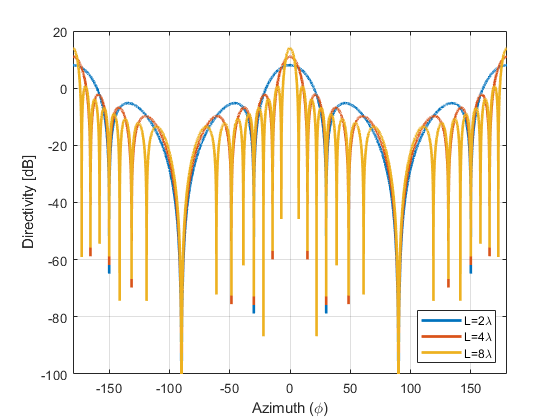

figure;
plot(phi, pow2db(dir_2(1,:)), "LineWidth",2); hold on;
plot(phi, pow2db(dir_4(1,:)), "LineWidth",2); hold on;
plot(phi, pow2db(dir_8(1,:)), "LineWidth",2); hold off;
xlabel("Azimuth (\phi)"); ylabel("Directivity [dB]");
ylim([-100,20]); xlim([-180,180]); grid on;
legend("L=2\lambda","L=4\lambda","L=8\lambda", "Location", "southeast");

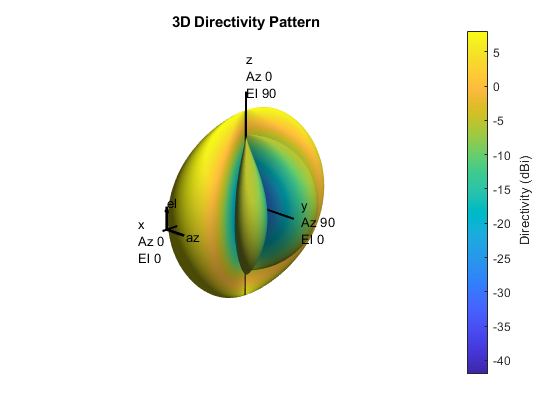

phasePattern = zeros(size(dir_2));
ant = phased.CustomAntennaElement(...
    'AzimuthAngles', phi, 'ElevationAngles', theta, ...
    'MagnitudePattern', pow2db(dir_2), ...
    'PhasePattern', phasePattern);
fc = 28e9;
ant.pattern(fc);

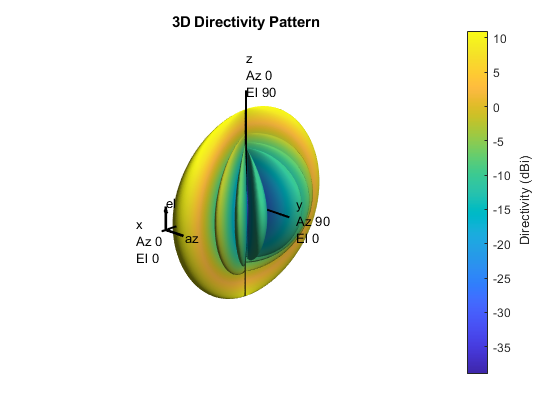

phasePattern = zeros(size(dir_4));
ant = phased.CustomAntennaElement(...
    'AzimuthAngles', phi, 'ElevationAngles', theta, ...
    'MagnitudePattern', pow2db(dir_4), ...
    'PhasePattern', phasePattern);
fc = 28e9;
ant.pattern(fc);

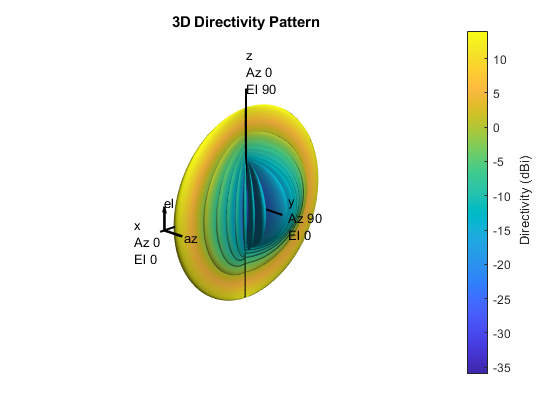

phasePattern = zeros(size(dir_8));
ant = phased.CustomAntennaElement(...
    'AzimuthAngles', phi, 'ElevationAngles', theta, ...
    'MagnitudePattern', pow2db(dir_8), ...
    'PhasePattern', phasePattern);
fc = 28e9;
ant.pattern(fc);

function prad=get_radiated_power(U,theta,phi,theta_range,phi_range)
    theta_len = length(theta);
    phi_len = length(phi);
    U_times_cos = U'.*cos(deg2rad(theta));
    %prad = sum(U_times_cos,'all')*deg2rad(theta_range)*deg2rad(phi_range)/(theta_len*phi_len);
    % the above formula gives the same results
    prad = 2*pi^2*mean(U_times_cos, "all");
end

function D=get_directivity(U, prad)
    D=U*4*pi/prad;
end